# Simulating sensors that have multiple pixel types and exposure times

*Developed by D. Cardinal, Stanford University, June, 2022*

*Initial target is Samsung's Corner Pixel Automotive technology*

In this script we allow comparisons between traditional HDR bracketing (a sequence of images some number of stops above and below a base value), manual bracketing with arbitrary exposures, and a simulated "corner pixel" sensor that records a single image but uses a compound pixel that has two (or more) different photosites with different properties.

In this case we simulate the compound pixel by allowing multiple exposures with different fill factors, that are treated as a single exposure. However we do allow for the case where the various sub-pixels vary in their exposure time. This is true of the Samsung design, for example, as a way of handling LED flicker.

By default the ISP does the scientifically-correct thing to combine the sensor images, by choosing between multiple photosites or captures by selecting the one with the largest total value without saturating (NEED TO FIX THIS). But you can experiment with other algorithms either in sensor or in a coded ISP.

ieInit();

% Select between a typical HDR scene, an extreme HDR scene,
% or our Chess Set scene rendered in 3d using pbrt-v4:
sceneType = 'Extreme'

sceneType = 'Extreme'


% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera();

% For Corner Pixel, we want an Auto-friendly sensor
% with larger main pixels than, for example, a smartphone
sensor = sensorFromFile('ar0132atSensorRGB.mat');

% To make life simple for now, use 1 for Fill
sensor = sensorSet(sensor,'fillfactor', 1.0);

% for a larger sensor we need different optics
oi = oiCreate();
oi = oiSet(oi, 'optics', opticsCreate('standard (1-inch)'));

% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor and optics
ourCamera.cmodules(1) = cpCModule('sensor', sensor,'oi',oi);


#### Here are several example scenes to choose from:

ourSceneFile = fullfile('StuffedAnimals_tungsten-hdrs.mat');
extremeSceneFile = fullfile('Feng_Office-hdrs.mat');
hdrScene = cpScene('iset scene files', 'isetSceneFileNames', ourSceneFile);

Reading multispectral data with mcCOEF.
Saved using svd method


extremeScene = cpScene('iset scene files', 'isetSceneFileNames', extremeSceneFile);

Reading multispectral data with mcCOEF.
Saved using svd method



% We can also experiment with a 3D pbrt scene:
scenePath = 'ChessSet';
sceneName = 'chessSet';
numRays = 64; filmResolution = 512;
pbrtScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays);

Read 9 materials and 3 textures..


% put our scene in an interesting room
pbrtScene.thisR.set('skymap', 'room.exr', 'rotation val', [-90 0 0]);

% Choose which one of our example scenes to use
switch sceneType
    case 'Extreme'
        showScene = extremeScene;
        baseExposure = .3;
    case 'HDR'
        showScene = hdrScene;
        baseExposure = .1;
    case 'pbrt'
        showScene = pbrtScene;
        baseExposure = .2;
end

#### Baseline Images

As baseline images we capture an image of the scene using a camera set to full Auto mode, as well as one set to a traditional bracketing (HDR) mode..

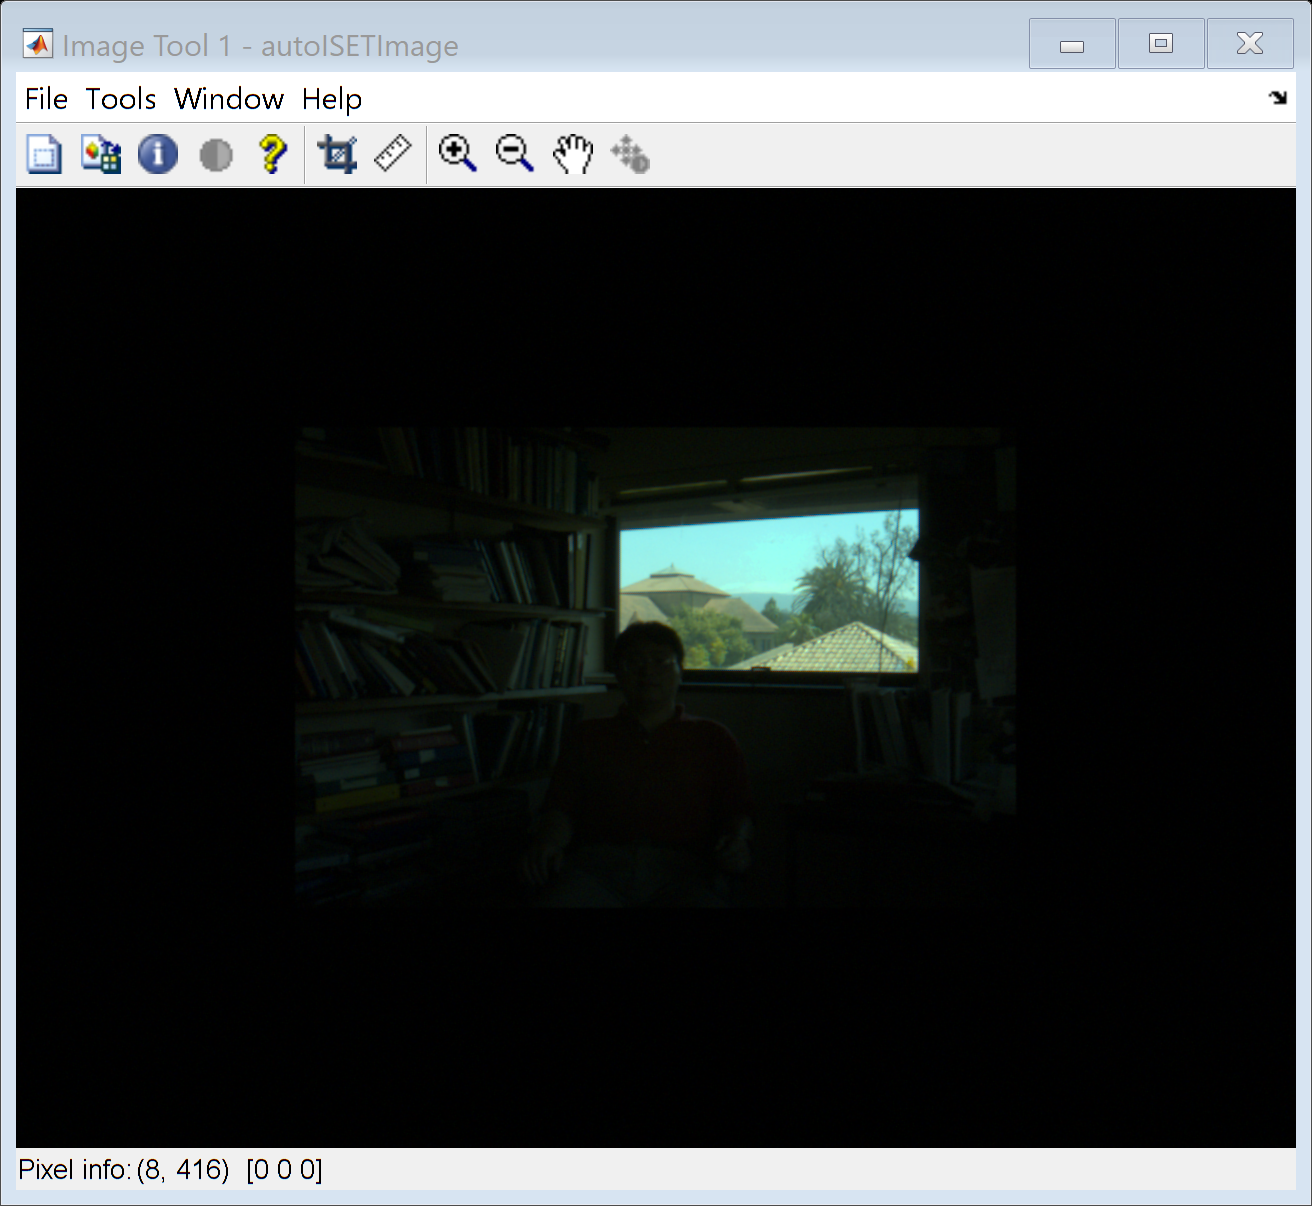

autoISETImage = ourCamera.TakePicture(showScene, 'Auto',...
    'imageName','ISET Scene in Auto Mode');
imtool(autoISETImage); 


% select whether to do 'simple' image combination
% in the sensor, or use a higher-level IP
insensorIP = true;
% Use a traditional HDR bracket (-1, 0, +1)
hdrImage = ourCamera.TakePicture(showScene, 'HDR',...
    'insensorIP',insensorIP,'numHDRFrames',3,...
    'imageName',sprintf('HDR Mode with %d frames',3));

#### Corner Pixel Simulation

Samgung's Corner Pixels are a traditional Bayer array of pixels (typically large pixels for low-light scenes, around 3 microns). But "in the corners" between the large photosites are smaller ones, perhaps 1 micron -- in a matching Bayer array. The sensor can lengthen the exposure time on the small pixels to help alleviate LED flickering issues that are an issue when identifying traffic lights.

We simulate the photosite sizes by choosing fill factors, and placing small photosites in the corner of the pixel. Exposure times can also be altered. While Samsung only has 2 photosites per pixel, we can simulate more if desired. Multiple exposure times can be set alongside fill factors.

% right now we manually set exposure times for the Manual
% mode, so those need to be tweaked as needed
cornerFillFactors = [1 .1];

cornerExpTimes = [baseExposure baseExposure];
cornerToneMap = 'longest';
cornerImage = ourCamera.TakePicture(showScene, 'Manual',...
    'insensorIP',insensorIP,'numHDRFrames',numel(cornerFillFactors),...
    'expTimes', cornerExpTimes, 'fillFactors', cornerFillFactors, ...
    'tonemap',cornerToneMap, ...
    'imageName','Corner Pixel Simulation');


#### Compare with Bracketed Images

Capture manual multi-exposures to compare with Corner Pixels. Key parameters are the exposure times and the tonemap parameter. Simple bracketed HDR uses "longest", where the longest non-saturated value is used. We also provide "largest" that simply looks for the largest raw value. 

For additional experimentation, you can set "inSensorIP to false, and work with code in the cpCamera's isp to do more sophisticated image combination (e.g. tonemapping).

% for modern Bayer sensors fill factor us usually close to 1
bracketFillFactors = [1 1];


Here you can play with how much you want to bracket. Traditional starts at -1, 0, +1, but for more extreme scenes or alternative approaches, you can vary the times and the number of exposures (if you change the number of exposure times, also make sure to change the number of fill factors to match.

bracketExpTimes = [baseExposure baseExposure/9];

% Longest is simple, traditional scene estimation
% (take longest non-saturated exposure)
% NB: This was designed for equal-area PDs
%     and I think will need to be augmented
%
% Largest is an experimental alternative that always selects
% the largest non-saturated value. 
%
bracketTonemap = 'longest';
bracketImage = ourCamera.TakePicture(showScene, 'Manual',...
    'insensorIP',insensorIP,'numHDRFrames',numel(bracketExpTimes),...
    'expTimes',bracketExpTimes, 'fillFactors',bracketFillFactors, ...
    'tonemap', bracketTonemap, ...
    'imageName','Manual Bracketing');


#### Visually compare our Results

Bracket: Fill= 1, 1, 3.000000e-01 Exp= 0.033, 108.000, 111.000, Tone: ngest
 Corner: Fill= 1, 0.1 & Exp= 0.300, 0.300, Tone: longest


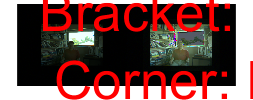

bFillFormat = repmat('%s ', 1, numel(bracketFillFactors));
bExpFormat = repmat('%2.3f ', 1, numel(bracketFillFactors));
caption = sprintf(['Bracket: Fill= ' bFillFormat ' Exp= ' bExpFormat ', Tone: %s\n', ...
    ' Corner: Fill= %s, %s & Exp= %2.3f, %2.3f, Tone: %s\n'], ...
    string(bracketFillFactors), bracketExpTimes, bracketTonemap, ...
    string(cornerFillFactors), cornerExpTimes, cornerToneMap);
    
cpCompareImages(bracketImage,cornerImage,caption);

#### Analyze the Images

The previous comparison helps provide a visual comparison, but if we want to analyze the images we can bring them up in ipWindows.

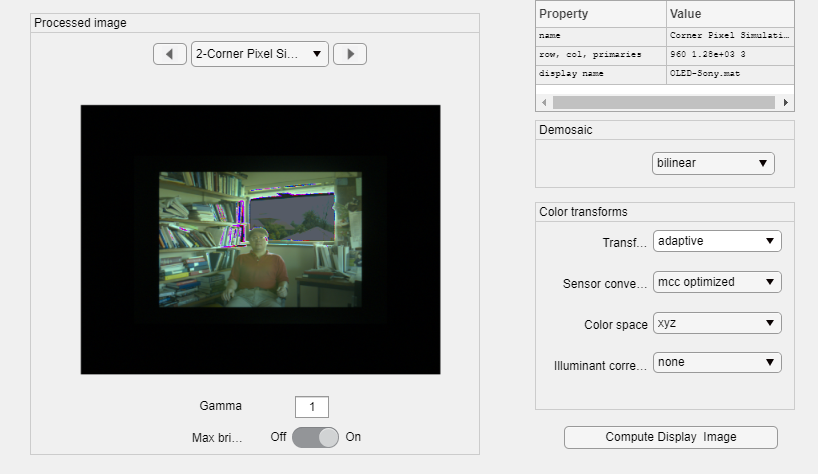

    ipWindow(bracketImage);
    ipWindow(cornerImage);

### Ideas for Further Work / Projects

How much does noise matter if the consumer is an ML system in a car?

What other tone map options might combine some of the advantages of "largest" and "longest"?